I = imread("664067.jpg");
I = rgb2gray(I);
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
imshow(I);
hold on;
plot(sift.selectStrongest(3))
num = sift.selectStrongest(1)

num =   SIFTPoints with properties:

          Scale: 12.4581
    Orientation: 0
         Octave: 2
          Layer: 3
       Location: [139.5743 134.5049]
         Metric: 0.0615
          Count: 1


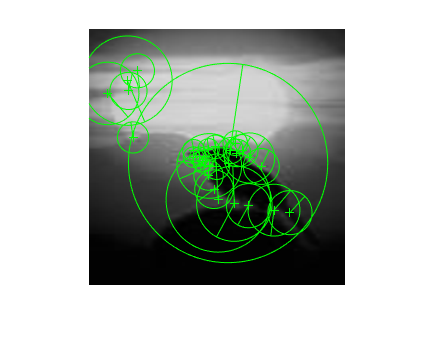

[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);

a = load('train.mat');

%CIFAR100
rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur'};
categories = {'cup','dinosaur','forest','hamster'};
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');

Error using imageDatastore (line 139)
Cannot find files or folders matching: 'cifar-100-matlab\CIFAR-100\TEST\cup'.

imds.ReadFcn = @readFunctionTrain;

% Change the number 50 to as many training images as you would like to use
% how does increasing the number of images change the 
% accuracy of the classifier?
[trainingSet, ~] = splitEachLabel(imds, 10, 'randomize'); 

%COREL80
rootFolder = 'CorelDB';
% categories = {'cup','dinosaur'};
categories = {'pet_dog','sc_sunset','wl_buttrfly','wl_deer'};
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imds.ReadFcn = @readFunctionTrain;

% Change the number 50 to as many training images as you would like to use
% how does increasing the number of images change the 
% accuracy of the classifier?
[trainingSet, ~] = splitEachLabel(imds, 10, 'randomize'); 

% X = dataset of images
F = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images and collect their SIFT features into a matrix
for i = 1:numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]);
    sift = detectSIFTFeatures(I);
    [features, sift_points] = extractFeatures(I, sift);
    F = [F features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end

D = 'C:\Users\user\Documents\MATLAB\vLSH-master\grey4';
S = dir(fullfile(D,'*'));
N = setdiff({S([S.isdir]).name},{'.','..'}); % list of subfolders of D.
for ii = 1:numel(N)
    T = dir(fullfile(D,N{ii},'*')); % improve by specifying the file extension.
    C = {T(~[T.isdir]).name}; % files in subfolder.
    for jj = 1:numel(C)
        F = fullfile(D,N{ii},C{jj});
        currentimage = imread(F);
        images{jj} = currentimage;
    end
end


% construct LSH hash tables for F

Q = 57; % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 2;    % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(F, L, M, W);

Creating table 1/2
	Projecting data...
	2968 buckets
	min / max size: 1 / 883
	mean / median: 1.119980e+01 / 2
Creating table 2/2
	Projecting data...
	3117 buckets
	min / max size: 1 / 1455
	mean / median: 1.066442e+01 / 2
Total time: 0.033743


[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(F(:, 1:Q), F, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.092268 seconds
Retrieving candidates from table 2
	-----> 0.103528 seconds
Removing duplicate candidates...
	-----> 0.002267 seconds
Performing knn search...
	-----> 0.005066 seconds
Calculating candidate sizes...
	-----> 0.005090 seconds


queryM = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          queryM(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

ids = unique(queryM);
N = numel(ids);
count = zeros(N,1);
for k = 1:N
%   count(k) = sum(sum(queryM==ids(k)));
  exp(N-k+1)
  count(k) = exp(N-k+1)*sum(sum(queryM==ids(k)));
end

ans = 8.6593e+16

ans = 3.1856e+16

ans = 1.1719e+16

ans = 4.3112e+15

ans = 1.5860e+15

ans = 5.8346e+14

ans = 2.1464e+14

ans = 7.8963e+13

ans = 2.9049e+13

ans = 1.0686e+13

ans = 3.9313e+12

ans = 1.4463e+12

ans = 5.3205e+11

ans = 1.9573e+11

ans = 7.2005e+10

ans = 2.6489e+10

ans = 9.7448e+09

ans = 3.5849e+09

ans = 1.3188e+09

ans = 4.8517e+08

ans = 1.7848e+08

ans = 6.5660e+07

ans = 2.4155e+07

ans = 8.8861e+06

ans = 3.2690e+06

ans = 1.2026e+06

ans = 4.4241e+05

ans = 1.6275e+05

ans = 5.9874e+04

ans = 2.2026e+04

ans = 8.1031e+03

ans = 2.9810e+03

ans = 1.0966e+03

ans = 403.4288

ans = 148.4132

ans = 54.5982

ans = 20.0855

ans = 7.3891

ans = 2.7183

%sorted = sort(count,1,'ascend')
ranks = sortrows([count ids],1,'descend')

ranks = 	1.0e+18 *

    9.7851    0.0000
    0.5734    0.0000
    0.0586    0.0000
    0.0517    0.0000
    0.0368    0.0000
    0.0143    0.0000
    0.0022    0.0000
    0.0017    0.0000
    0.0006    0.0000
    0.0004    0.0000


sum(queryM==ids(k))

ans =      0     1     0     0     0     0     0     0     0     0     0     0     0     2     2     0     1     1     0     0     0     0     1     0     0     0


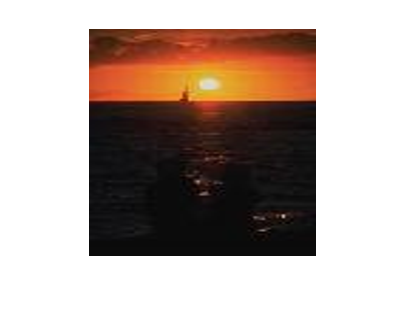

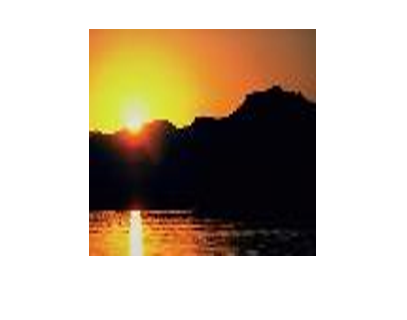

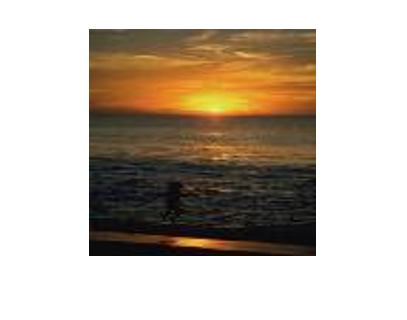

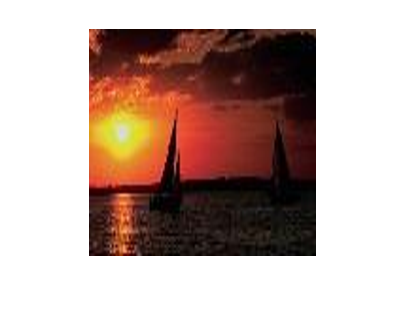

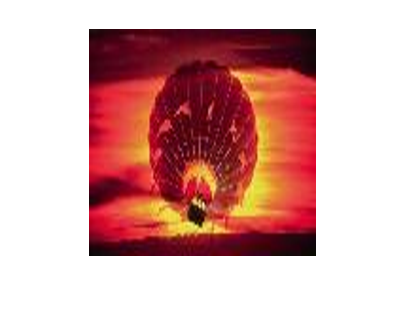

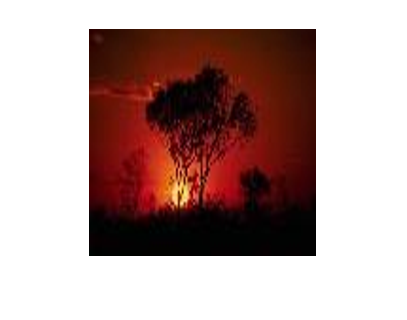

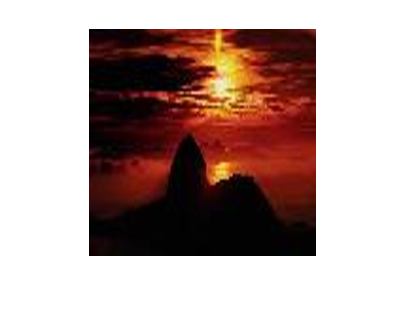

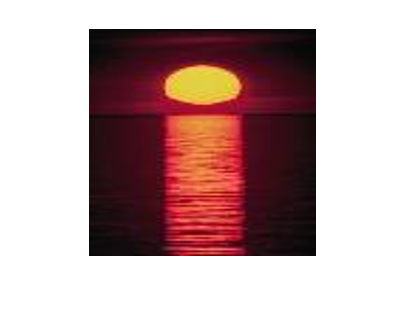

for pic = 1:10
    I = readimage(trainingSet, ranks(pic, 2));
    figure,
    imshow(I);
end

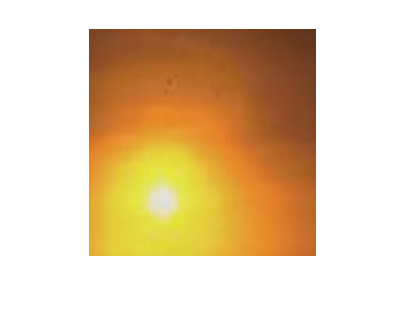

I =   Image with properties:

           CData: [227×227×3 uint8]
    CDataMapping: 'direct'

  Show all properties


I = imshow(readimage(trainingSet, 6))

I = imread("car2.jpg");
I = rgb2gray(I);
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
imshow(I);
hold on;
plot(sift.selectStrongest(3))
num = sift.selectStrongest(1)
[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


% query for image
% query = image
I = imread(query);
% check if it is not already grey scale
if size(I,3)==3
    I = rgb2gray(I);
end

I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
[features, sift_points] = extractFeatures(I, sift);
Qfeatures = rot90(features);




% Perform simple LSH search on the first Q elements of X
[idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
% is the same with: [idsSIMPLE cand_sizeSIMPLE binsFound_ratiosSIMPLE] = lshSearch(X(:, 1:Q), X, lshStruct, K, 0);

% Perform multiprobe LSH search on the first Q elements of X
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(X(:, 1:Q), X, lshStruct, K, T);

% Perform brute force KNN on the first Q elements of X
% [~, idsTRUE] = knn(X(:, 1:Q), X, K);

% Compute recalls
% recallSIMPLE = compute_recall(idsTRUE, idsSIMPLE);
% recallMULTIPROBE = compute_recall(idsTRUE, idsMULTIPROBE);

% Compute selectivities (i.e. mean size of distinct candidates for each query)
% selectivitySIMPLE = sum(cand_sizeSIMPLE) / (Q * size(X, 2));
% selectivityMULTIPROBE = sum(cand_sizeMULTIPROBE) / (Q * size(X, 2));
